# project 3

# Heath Ferris(UHid: 1162824)

### Part 1

N = 256

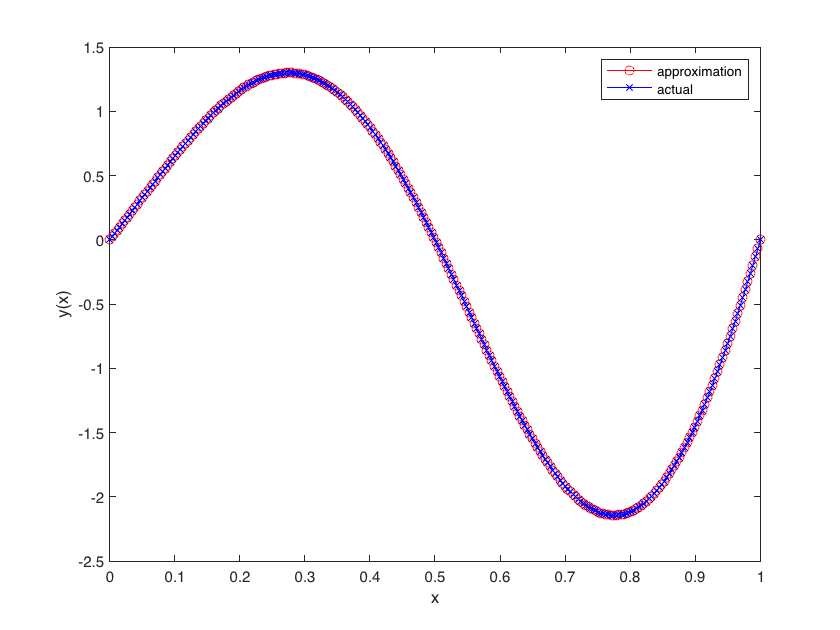

N = 512

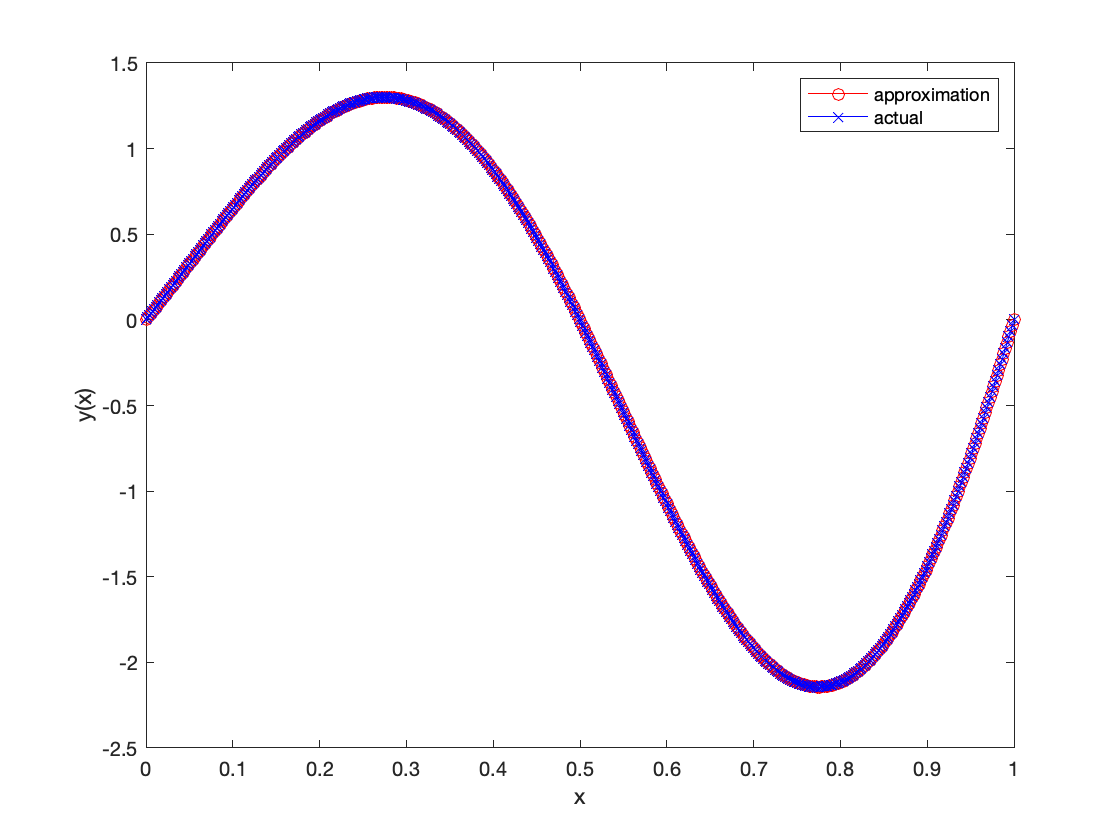

N = 1024

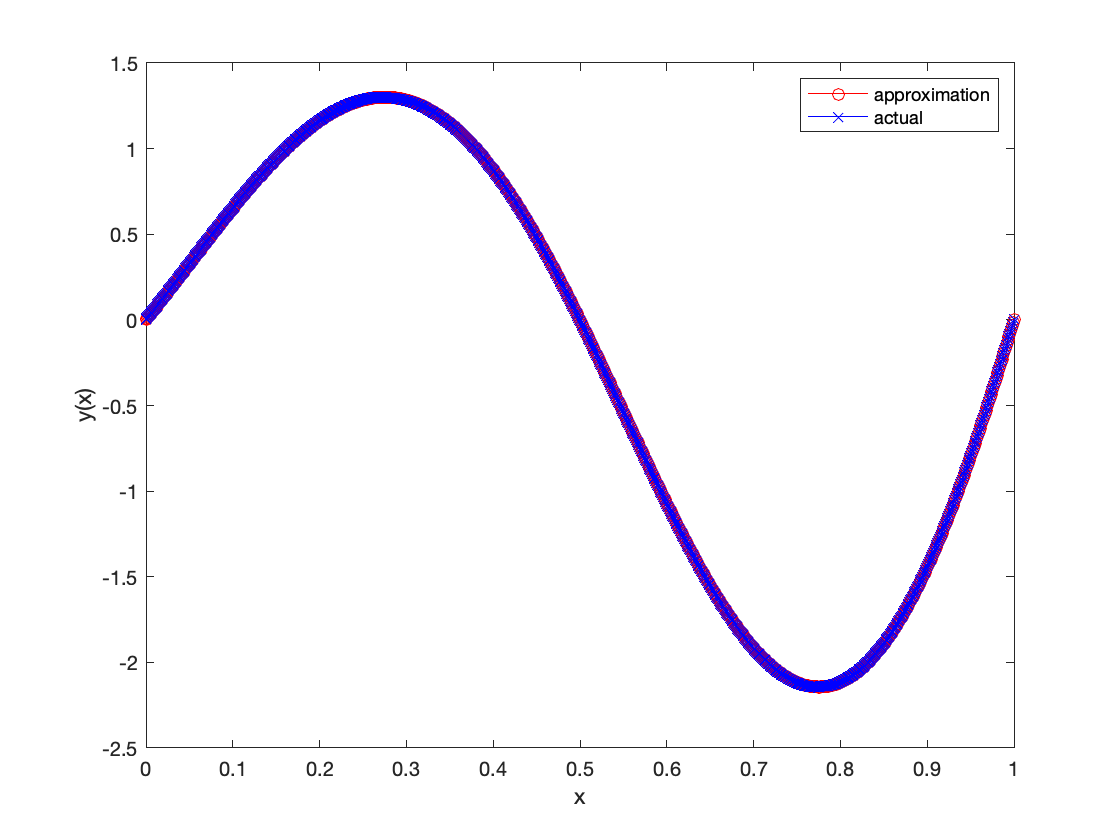

N = 2048

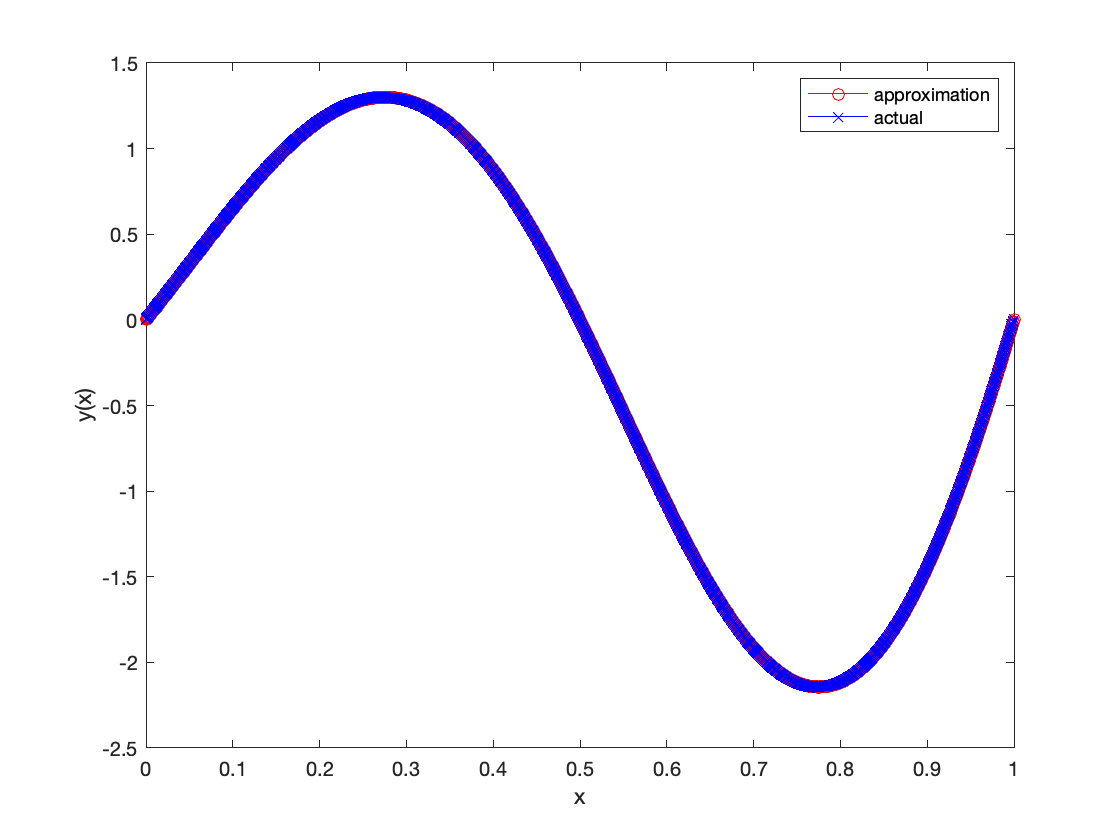

N = 4096

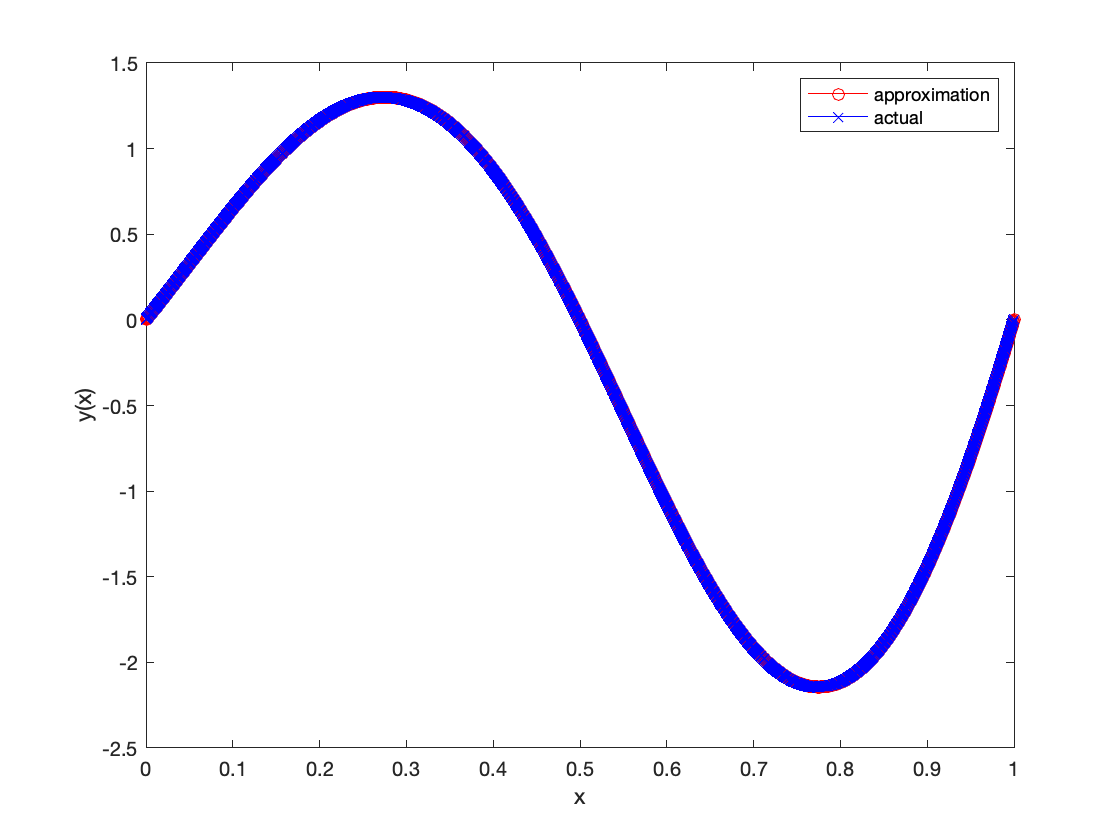

clear all; 
close all;
ya = inline('sin(2*pi*x).*exp(x)', 'x');
fa = inline('(-(2*pi)^2+1)*sin((2*pi)*x).*exp(x)+2*(2*pi)*cos(2*pi*x).*exp(x)','x');
L = 1;
alpha = ya(0);
beta =  ya(L);
Ng = 2.^(8:12);
for i = 1:length(Ng)

    N = Ng(i)
    h = L/(N+1);


    x = (0:h:L)'; 

    yvec = ya(x); % the known analytic solution
 
    fvec = fa(x(2:N+1)); % interior points

    y =  twopBVP(fvec,alpha,beta,L,N);

    figure(i)
    plot(x,y,'r-o',x,yvec,'b-x')
    legend('approximation','actual')
    xlabel('x')
    ylabel('y(x)')

    error(i) = norm(yvec-y);
end

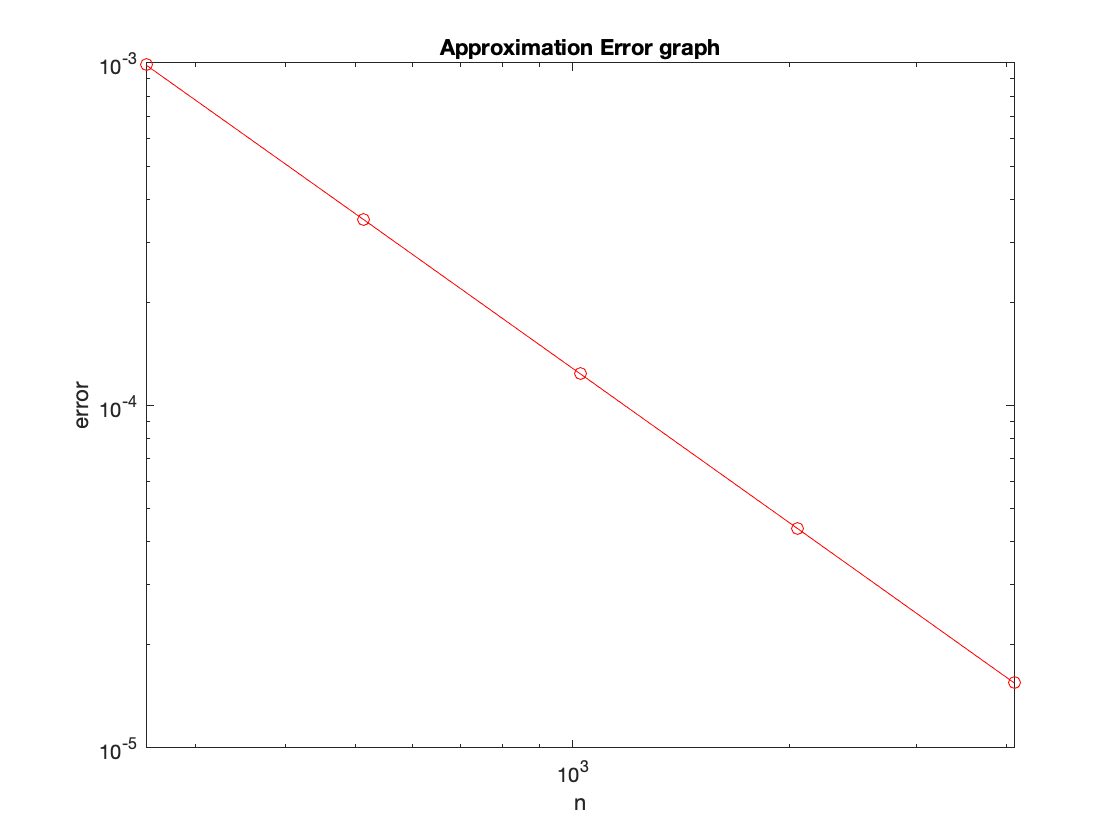


figure(i+1)
%figure(1)
loglog(Ng,error,'r-o')
title('Approximation Error graph')
xlabel('n')
ylabel('error')

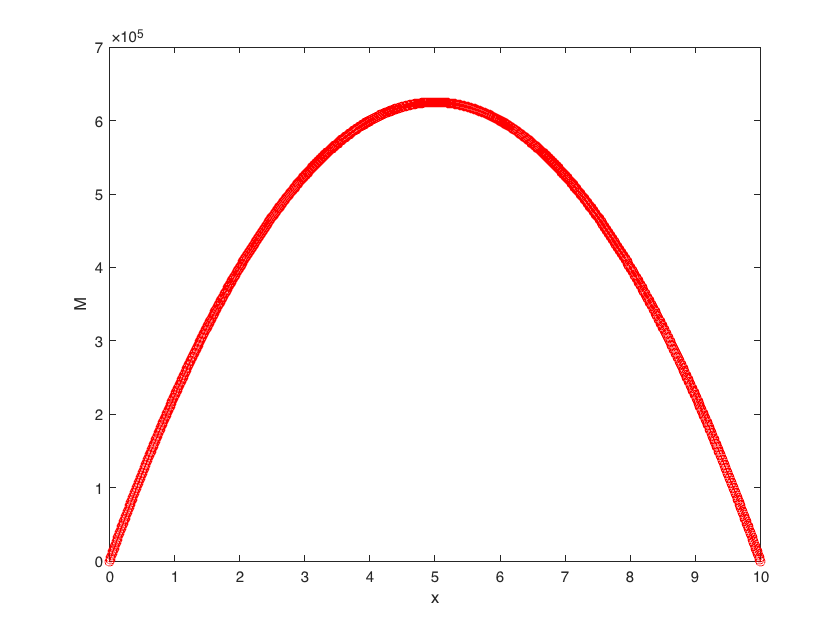

clear all;
close all;


L = 10; 
E = 1.9E11;  


N = 10^3-1;
h = L/(N+1);
x = (0:h:L)'; 
qvec = -50*10^3*ones(N,1); 
M =  twopBVP(qvec,0,0,L,N);
Ivec = 10^(-3)*(3-2*(cos(pi*x(2:N+1)/L)).^12);
fvec = M(2:N+1)./(E*Ivec);
u =  twopBVP(fvec,0,0,L,N);
figure(1)
plot(x,M,'r-o')
xlabel('x')
ylabel('M')

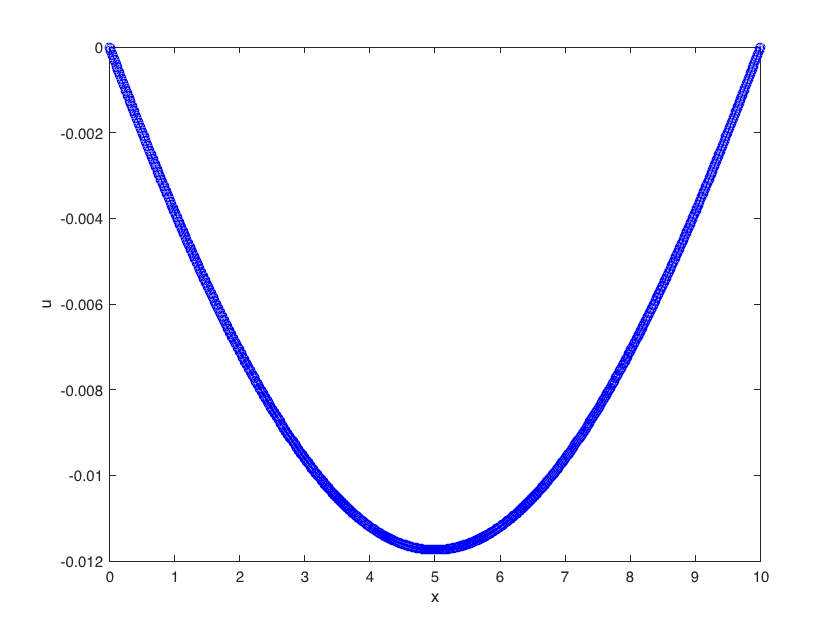


figure(2)
plot(x,u,'b-o')
xlabel('x')
ylabel('u')



disp('Deflection at the midpoint in millimeter (mm)')

Deflection at the midpoint in millimeter (mm)


u((N+1)/2+1)*1E3

ans = -11.7411

L = 1;
Ng = 2.^(8:12);

for i = 1:length(Ng)
    N = Ng(i)
    h = L/(N+1);
    h = L/(N+1);
    e = ones(N,1);
    A = 1/(h^2)*spdiags([e,-2*e,e],[-1,0,1], N,N);
    [V,D] = eigs(A,3,'SM');
end

N = 256

N = 512

N = 1024

N = 2048

N = 4096

## part 2

### task 2.1

finding true eigenvalue of the y		

Sturm–Liouville 

true solution


$$\begin{array}{l}
\textrm{for}\;\lambda >0,\textrm{then}\;\textrm{solotion}\;\textrm{is}\;\textrm{trivial}\\
\textrm{consider}\\
{u^{\prime } }^{\prime } =-\lambda *u\;\;\left(\lambda >0\right)\\
\textrm{eigent}\;\textrm{mode}:\\
u\left(x\right)=c_1 *\cos \left(\sqrt{\lambda }x\right)+c_2 *\sin \left(\sqrt{\lambda }*x\right)\\
u\left(0\right)=c_1 =0\\
u\left(1\right)=c_2 *\sin \left(\sqrt{\;\lambda }\right)=0\\
\textrm{so}\;\textrm{the}\;\textrm{eigent}\;\textrm{value}\;\textrm{is}\;\\
\lambda_n ={\left(n*\pi \right)}^2 \;\textrm{for}\;n\;\textrm{interger}\\
\textrm{so}\;\textrm{eigent}\;\textrm{mode}\;\textrm{is}\;\;\sin \left(n*\pi *x\right)
\end{array}$$


numerical solution:


$$\begin{array}{l}
\frac{u_{n-1} -2u_n +u_{n+1} }{{\left(\Delta x\right)}^2 }=-\lambda *u_n \\
\textrm{so}\\
u_{n-1} -2*u_n +u_{n+1} =-\lambda *u_n *\Delta_x^2 
\end{array}$$


clear all;
close all;
N=499;
delta_x=1/(N+1);
tridiagonal= zeros(N,N);
lambda=pi^2;
for i= 1:N
    tridiagonal(i,i)=-2;
    tridiagonal(i+1,i)=1;
    tridiagonal(i,i+1)=1; 
    u(i,1)=i*delta_x;
end
tridiagonal=tridiagonal(1:N,1:N)/delta_x^2;
[eig_vec eig_val]= eig(tridiagonal)

eig_vec =     0.0004   -0.0008   -0.0012    0.0016    0.0020   -0.0024   -0.0028    0.0032    0.0036   -0.0040   -0.0044    0.0048    0.0052   -0.0056   -0.0060    0.0063    0.0067   -0.0071   -0.0075    0.0079    0.0083   -0.0087   -0.0091    0.0095    0.0099   -0.0103   -0.0107    0.0111    0.0115   -0.0119   -0.0122    0.0126    0.0130   -0.0134   -0.0138    0.0142    0.0146   -0.0150   -0.0153    0.0157    0.0161   -0.0165   -0.0169    0.0173    0.0176   -0.0180   -0.0184    0.0188    0.0192   -0.0195
   -0.0008    0.0016    0.0024   -0.0032   -0.0040    0.0048    0.0056   -0.0063   -0.0071    0.0079    0.0087   -0.0095   -0.0103    0.0111    0.0119   -0.0126   -0.0134    0.0142    0.0150   -0.0157   -0.0165    0.0173    0.0180   -0.0188   -0.0195    0.0203    0.0210   -0.0218   -0.0225    0.0233    0.0240   -0.0248   -0.0255    0.0262    0.0269   -0.0276   -0.0284    0.0291    0.0298   -0.0305   -0.0312    0.0319    0.0325   -0.0332   -0.0339    0.0346    0.0352   -0.0359   -0.036

eig_val = 	1.0e+05 *

   -9.9999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -9.9996         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

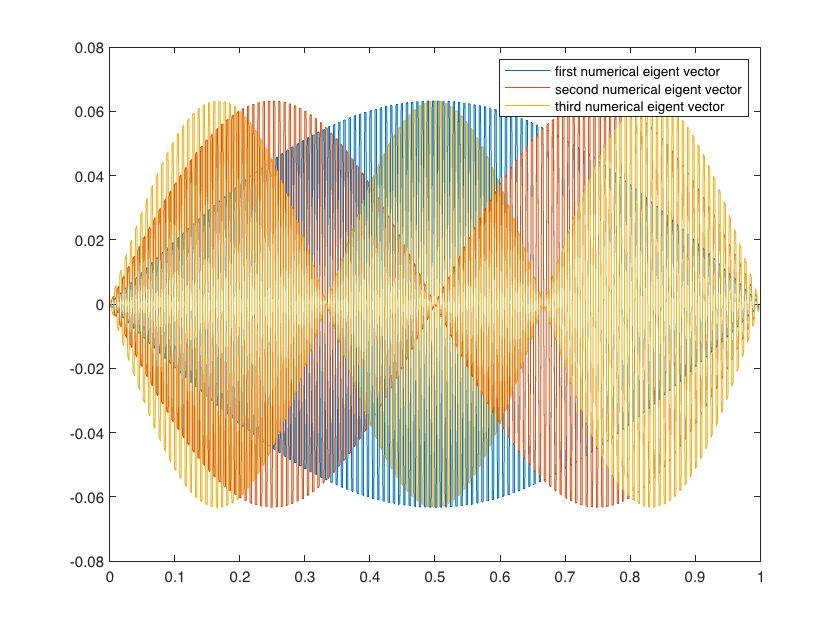

plot(1/500:1/500:1-1/500, eig_vec(1,:))
hold on
plot(1/500:1/500:1-1/500, eig_vec(2,:))
plot(1/500:1/500:1-1/500, eig_vec(3,:))
legend('first numerical eigent vector','second numerical eigent vector','third numerical eigent vector')
hold off

true solution plot

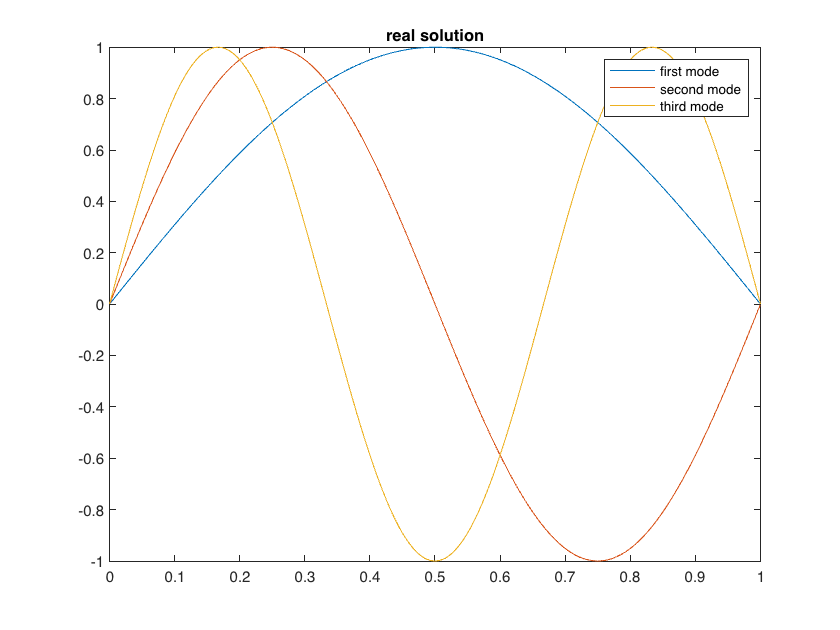

first_mode=inline('sin(pi*x)','x');
second_mode= inline('sin(2*pi*x)','x');
third_mode= inline('sin(3*pi*x)','x');

figure(1)
xlim([0,1])
plot(0:1/500:1, first_mode(0:1/500:1))
hold on
plot(0:1/500:1, second_mode(0:1/500:1))
plot(0:1/500:1, third_mode(0:1/500:1))
title('real solution')
legend("first mode", "second mode", "third mode")

### task 2.2


$$\begin{array}{l}
{\psi^{\prime } }^{\prime } -V\left(x\right)*\psi =-E*\psi \\
\textrm{for}\;\textrm{particple}\;\textrm{in}\;\textrm{the}\;\textrm{box}\;\textrm{problem}\\
V\left(x\right)=0\;\textrm{if}\;x\in \left\lbrack 0,1\right\rbrack \;\textrm{and}\;V\left(x\right)=\infty \;\textrm{else}\\
\textrm{the}\;\textrm{equation}\;\textrm{reduce}\;\textrm{as}\;\textrm{follow}\\
{\psi^{\prime } }^{\prime } =-E*\psi \\
\psi \left(0\right)=\psi \left(1\right)=0\\
\textrm{so}\;\textrm{as}\;\textrm{before}\\
E={\left(n*\pi \right)}^2 \\
\psi \left(x\right)=\sin \left(n*\pi *x\right)\\
\textrm{normalize}\;\textrm{the}\;\textrm{wave}\;\textrm{equation}\\
\int_0^1 {c*\sin \left(n*\pi *x\right)}^2 \textrm{dx}=1\\
\textrm{so}\;c=\frac{1}{2}\\
\Rightarrow \psi \left(x\right)=\frac{1}{2}*\sin \left(n*\pi *x\right)
\end{array}$$


code to check

idea


$$\left(D_x^2 -V\left(x\right)\right)\psi =-E*\psi$$


% V=0 so D^2 *psi= -E*psi
% the result will be similar to the last problem in 2.1


V(x)=700*(0.5-|x-0.5|)

clear all;
close all;
V= inline('700*(0.5-abs(x-0.5))','x');
N=499;
delta_x=1/(N+1)

delta_x = 0.0020

for i=1:N
    tridiagonal(i,i)=-2-V(i/(N+1));
    tridiagonal(i+1,i)=1;
    tridiagonal(i,i+1)=1; 
    u(i,1)=i*delta_x;
end

[wave_function  energy]= eig(tridiagonal)

wave_function =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0   

energy =  -352.9613         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0 -351.1951         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

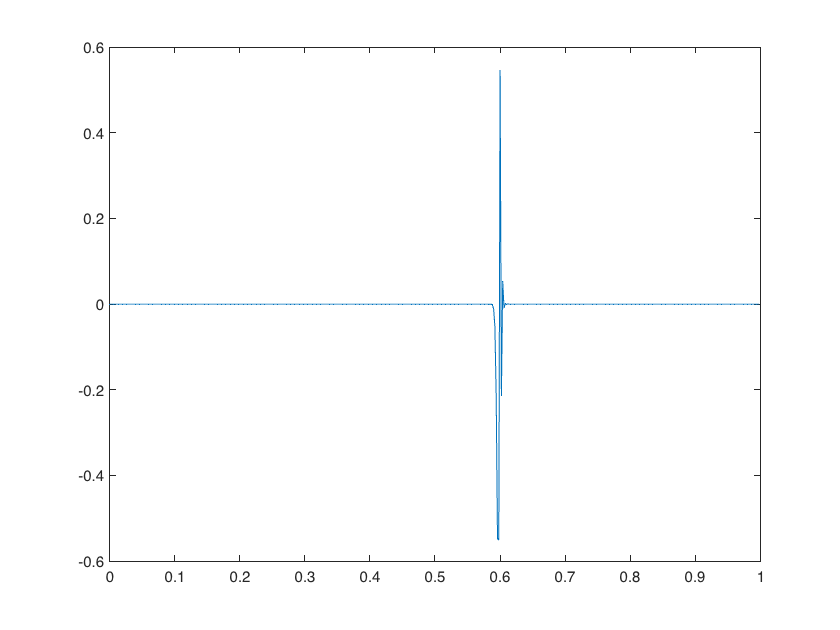

plot(0:1/500:1-1/500, wave_function(:,100))

## function

function y =  twopBVP(fvec,alpha,beta,L,N)


h = L/(N+1);
b  = fvec*h^2;
b(1) = b(1) - alpha;
b(N) = b(N) - beta;

e = ones(N,1);
A = spdiags([e,-2*e,e],[-1,0,1], N,N);

y = [alpha;A\b;beta];

end